# Assignment 2

## initialize

close all;
clc

## 1. parameters

% physical params
g = 9.8;

% vehicle params
weight = 1807.2; % kg
wheelbase = 2950*10^-3; % mm->m
R_tire = 402*10^-3; % mm->m
beta_1 = 3.538;
beta_2 = 2.06;
beta_3 = 1.404;
beta_4 = 1;
beta_5 = 0.713;
beta_6 = 0.582;
beta_dif = 4.1;

% engine params
speed_max = 6700; % rpm
speed_min = 725; % rpm
omega_max = speed_max*0.1047198; % rpm->rad/s
omega_min = speed_min*0.1047198; % rpm->rad/s, idle

yita_d = 1; % differencial efficiency
yita_g = 1; % gear box efficiency

% resistance params
%%%%%%%%%%%%%%%%%%%%% it hasn't been done yet%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mu_R = 1;
gradient_degree = 45;
gradient = deg2rad(gradient_degree);
A = 3; % m^2
rho = 0.1;
c_d = 0.5; % drag coefficient

% simulation params
dt = 0.01; % s

## torque engine speed

### map

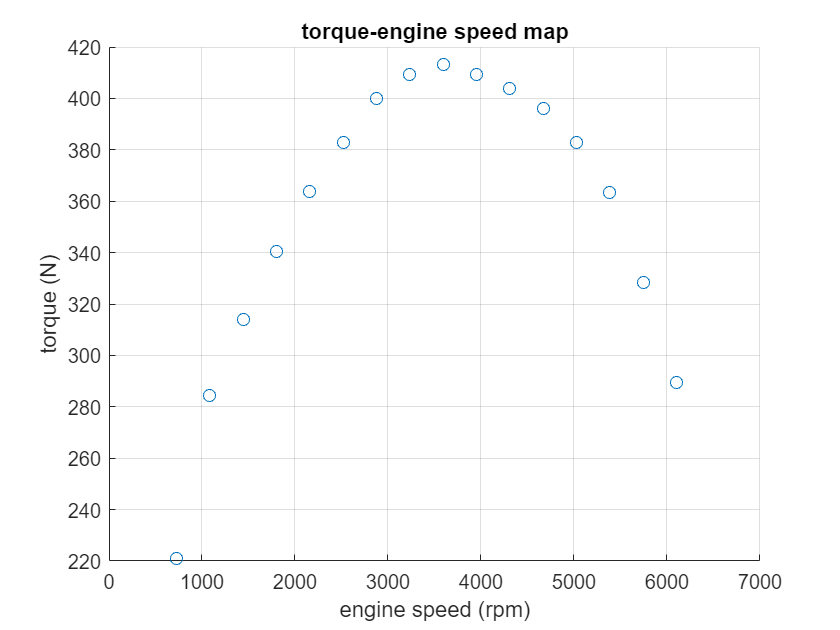

% the data is extracted from the carsim
% map_engine_spped = [400 508 617 725 1083 1442 1800 2158 2517 2875 3233 3592 3950 4308 4667 5025 5383 5742 6100 6500 6700];
% map_torque = [0 140.57 202.03 221.15 284.38 314.16 340.56 363.84 382.8 399.96 409.2 413.16 409.2 403.84 396 382.8 363.32 328.55 289.4 -106.92 -108.24];
map_engine_spped = [725 1083 1442 1800 2158 2517 2875 3233 3592 3950 4308 4667 5025 5383 5742 6100];
map_torque = [221.15 284.38 314.16 340.56 363.84 382.8 399.96 409.2 413.16 409.2 403.84 396 382.8 363.32 328.55 289.4];
scatter(map_engine_spped,map_torque)
title("torque-engine speed map");
xlabel("engine speed (rpm)");
ylabel("torque (N)");
grid on;

### poly fit

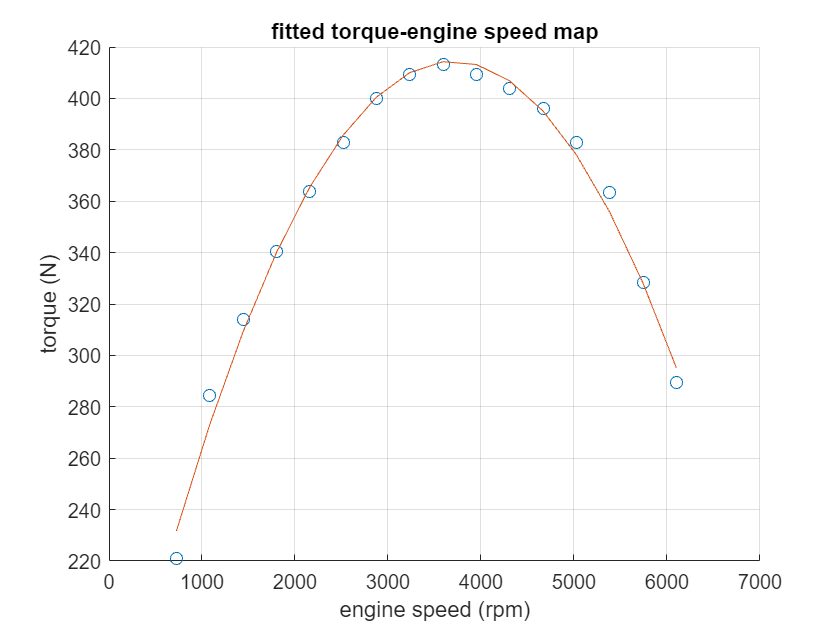

[p,ErrorEst] = polyfit(map_engine_spped,map_torque,2);
hold on;
title("fitted torque-engine speed map");
pop_fit = polyval(p,map_engine_spped,ErrorEst);
plot(map_engine_spped,pop_fit)

## Torque Engine Speed Map with Different Gear Box

This is Torque (Nm) vs. Wheel Speed (rpm)

hold off;

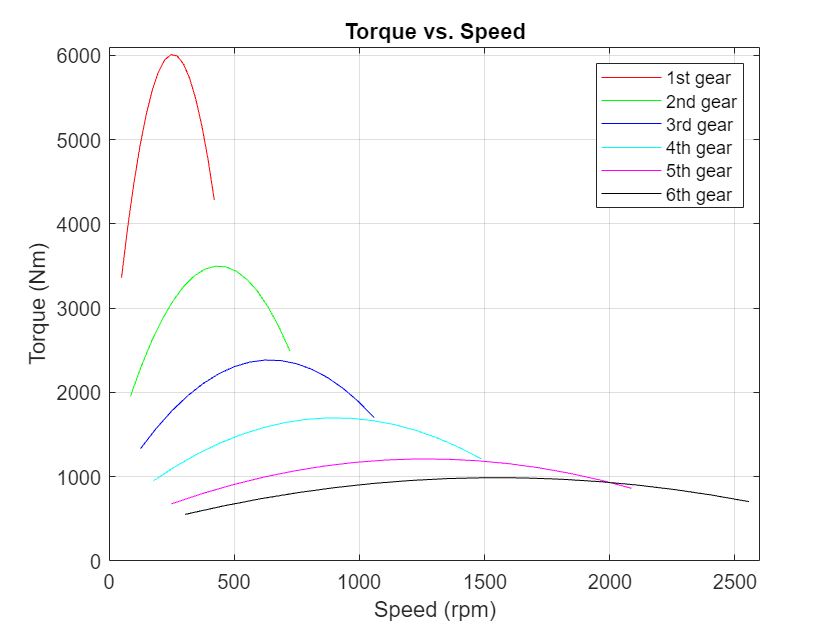

% calculate the torque of each gear
x1 = map_engine_spped / beta_dif / beta_1;% * R_tire * 2 * pi * 3.6 / 60;
y1 = beta_dif * beta_1 * polyval(p, map_engine_spped, ErrorEst);
x2 = map_engine_spped / beta_dif / beta_2;% * R_tire * 2 * pi * 3.6 / 60;
y2 = beta_dif * beta_2 * polyval(p, map_engine_spped, ErrorEst);
x3 = map_engine_spped / beta_dif / beta_3;% * R_tire * 2 * pi * 3.6 / 60;
y3 = beta_dif * beta_3 * polyval(p, map_engine_spped, ErrorEst);
x4 = map_engine_spped / beta_dif / beta_4;% * R_tire * 2 * pi * 3.6 / 60;
y4 = beta_dif * beta_4 * polyval(p, map_engine_spped, ErrorEst);
x5 = map_engine_spped / beta_dif / beta_5;% * R_tire * 2 * pi * 3.6 / 60;
y5 = beta_dif * beta_5 * polyval(p, map_engine_spped, ErrorEst);
x6 = map_engine_spped / beta_dif / beta_6;% * R_tire * 2 * pi * 3.6 / 60;
y6 = beta_dif * beta_6  * polyval(p, map_engine_spped, ErrorEst);

plot(x1, y1, 'r', x2, y2, 'g', x3, y3, 'b', x4, y4, 'c', x5, y5, 'm', x6, y6, 'k');
legend('1st gear', '2nd gear', '3rd gear', '4th gear', '5th gear', '6th gear');
title('Torque vs. Speed');
xlabel('Speed (rpm)');
ylabel('Torque (Nm)');
xlim([0 2600])
ylim([0 6100])
grid on;

## Traction Force vs Vehicle Speed

Traction Force (N) vs Vehicle Speed (m/s)

hold off;

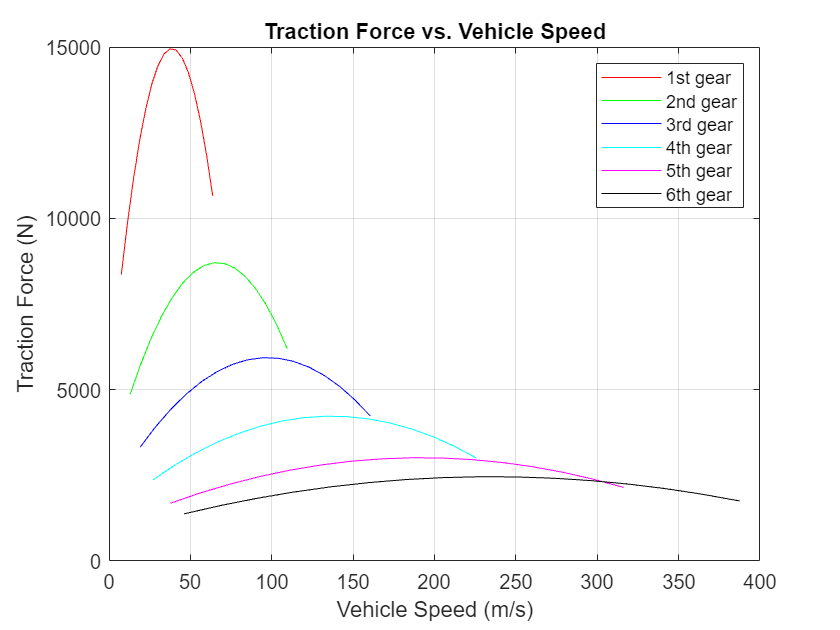

% convert the Wheel torque to Traction Force
y11 = y1/R_tire;
y12 = y2/R_tire;
y13 = y3/R_tire;
y14 = y4/R_tire;
y15 = y5/R_tire;
y16 = y6/R_tire;

x11 = x1 * R_tire * 2 * pi * 3.6 / 60;
x12 = x2 * R_tire * 2 * pi * 3.6 / 60;
x13 = x3 * R_tire * 2 * pi * 3.6 / 60;
x14 = x4 * R_tire * 2 * pi * 3.6 / 60;
x15 = x5 * R_tire * 2 * pi * 3.6 / 60;
x16 = x6 * R_tire * 2 * pi * 3.6 / 60;

plot(x11, y11, 'r', x12, y12, 'g', x13, y13, 'b', x14, y14, 'c', x15, y15, 'm', x16, y16, 'k');
legend('1st gear', '2nd gear', '3rd gear', '4th gear', '5th gear', '6th gear');
title('Traction Force vs. Vehicle Speed');
xlabel('Vehicle Speed (m/s)');
ylabel('Traction Force (N)');
grid on;

### Resistant Force with different gear box sets

#### resistance formulation

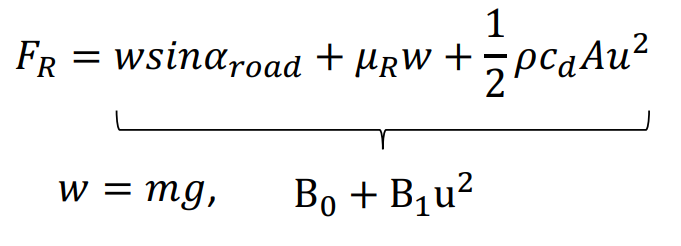

hold on;
% the param of B0 and B1
B0 = weight * g * sin(gradient) + mu_R * weight

B0 = 1.4330e+04

B1 = 0.5 * rho * c_d * A

B1 = 0.0750

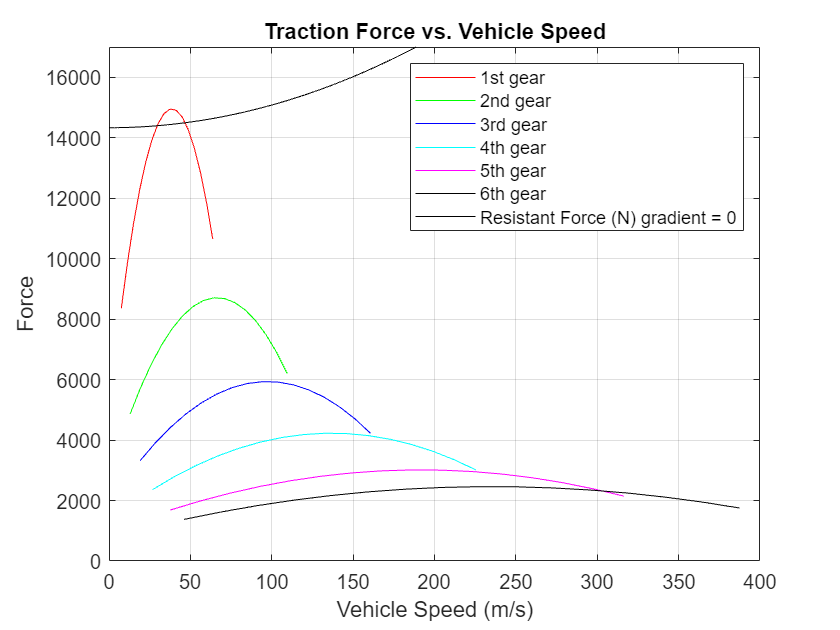

% so we can plot the relation with the vehicle speed and the resistance
% force
x_r = 0:0.1:400;
F_r = B0 + B1*x_r.^2;

plot(x_r,F_r,'k');
legend('1st gear', '2nd gear', '3rd gear', '4th gear', '5th gear', '6th gear', 'Resistant Force (N) gradient = 0');
title('Traction Force vs. Vehicle Speed');
xlabel('Vehicle Speed (m/s)');
ylabel('Force');
ylim([0 17000]);